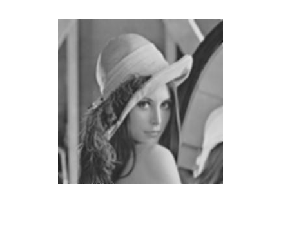

clc;clear all
six=im2gray(imread('girl.jpg'));
imshow(six)

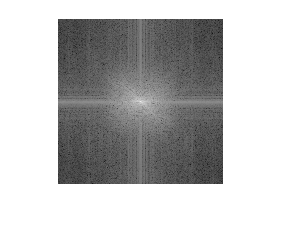

sixf=fftshift(fft2(six));
fftshow(sixf)

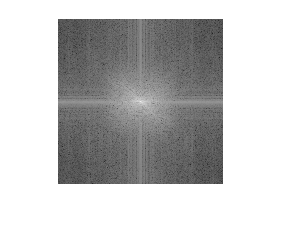

for i=1:256
    for j=1:256
        if sqrt((i-128).^2+(j+128).^2)<=96
            sixf(i,j)=sixf(i,j)*(0.5+3.5*(sqrt((i-128).^2+(j+128).^2)/96));
        end
        if sqrt((i-128).^2+(j+128).^2)>=96
            sixf(i,j)=sixf(i,j)*4;
        end
    end
end
fftshow(sixf)

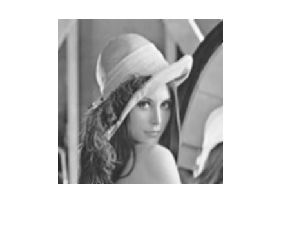

fftshow(ifft2(sixf),'abs')